We plot $|\Phi(x)|$ over the interval $[-1,1]$ with equispaced nodes for different values of $n$. 

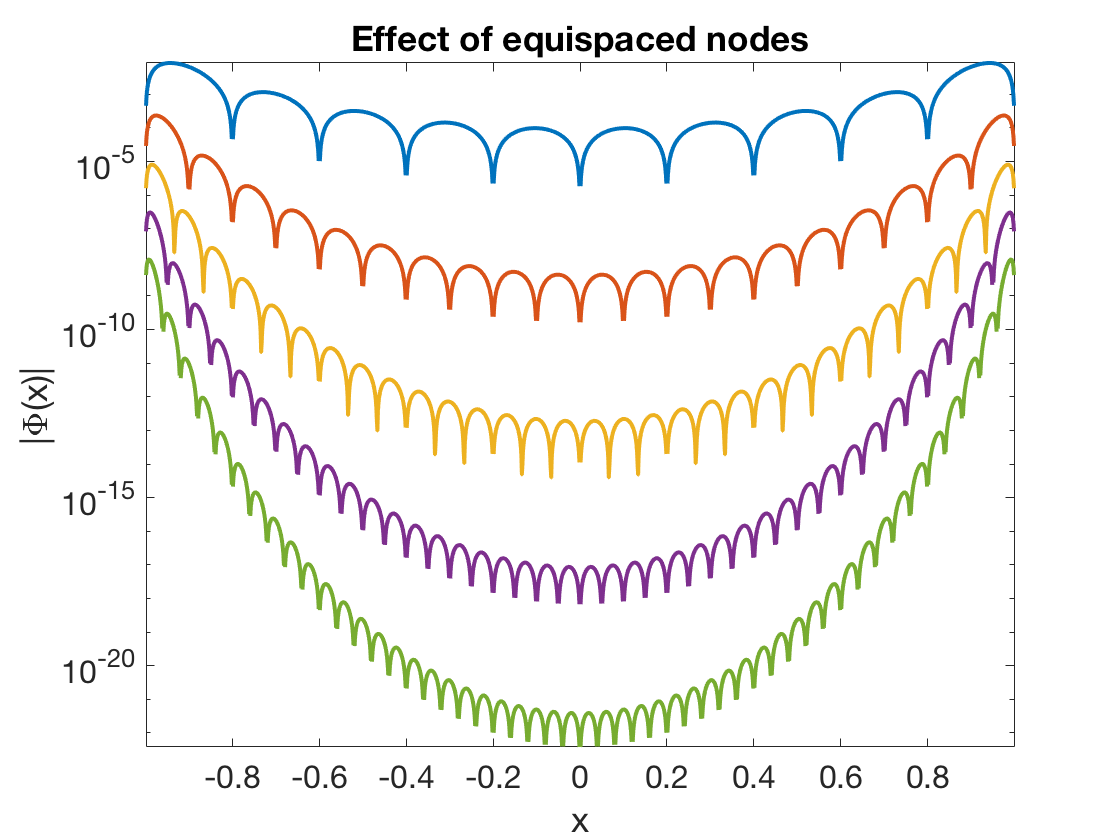

x = linspace(-1,1,1601)';
Phi = zeros(size(x));
for n = 10:10:50
    t = linspace(-1,1,n+1)';
    for k = 1:length(x)
        Phi(k) = prod(x(k)-t);
    end
    semilogy(x,abs(Phi)), hold on
end
axis tight, title('Effect of equispaced nodes')    % ignore this line
xlabel('x'), ylabel('|\Phi(x)|')   % ignore this line

(Each time $\Phi$ passes through zero at an interpolation node, the value on the log scale should go to $-\infty$, which explains the numerous cusps on the curves.) Two observations are important: First, the size of $|\Phi|$ decreases exponentially at each fixed location in the interval (because the spacing between curves is constant for constant increments of $n$). Second, $|\Phi|$ is larger at the ends of the interval than in the middle, by an exponentially growing factor.